% Boedo and Prantil 1998: corrected solution of clamped ring plate with edge point load
% https://ascelibrary.org/doi/epdf/10.1061/%28ASCE%290733-9399%281998%29124%3A6%28696%29

## Comparison against Boedo paper

clear
N = 100;

lam = 2/3;
nu = 0.3;

theta = 0:pi/8:pi;
rho = 2/3;
[~,Mr_nondim,abcd] = calc_plate(lam,nu,theta,rho,N);

format shortE
abcd(1:10,:)

ans =   -2.4628e-01   2.6060e-01  -2.1064e-01  -2.5000e-01
   5.6862e-02  -1.1715e-01   8.7971e-02   5.0000e-01
   1.4973e-01  -3.6700e-02   2.3133e-02  -1.1135e-01
   5.9034e-02  -1.8376e-02   8.2143e-03  -2.8530e-02
   3.3377e-02  -1.1777e-02   3.0900e-03  -9.4233e-03
   2.1425e-02  -8.5354e-03   1.1572e-03  -3.2917e-03
   1.4625e-02  -6.5209e-03   4.2958e-04  -1.1699e-03
   1.0416e-02  -5.1113e-03   1.5962e-04  -4.2191e-04
   7.6881e-03  -4.0805e-03   5.9845e-05  -1.5477e-04
   5.8546e-03  -3.3123e-03   2.2727e-05  -5.7808e-05


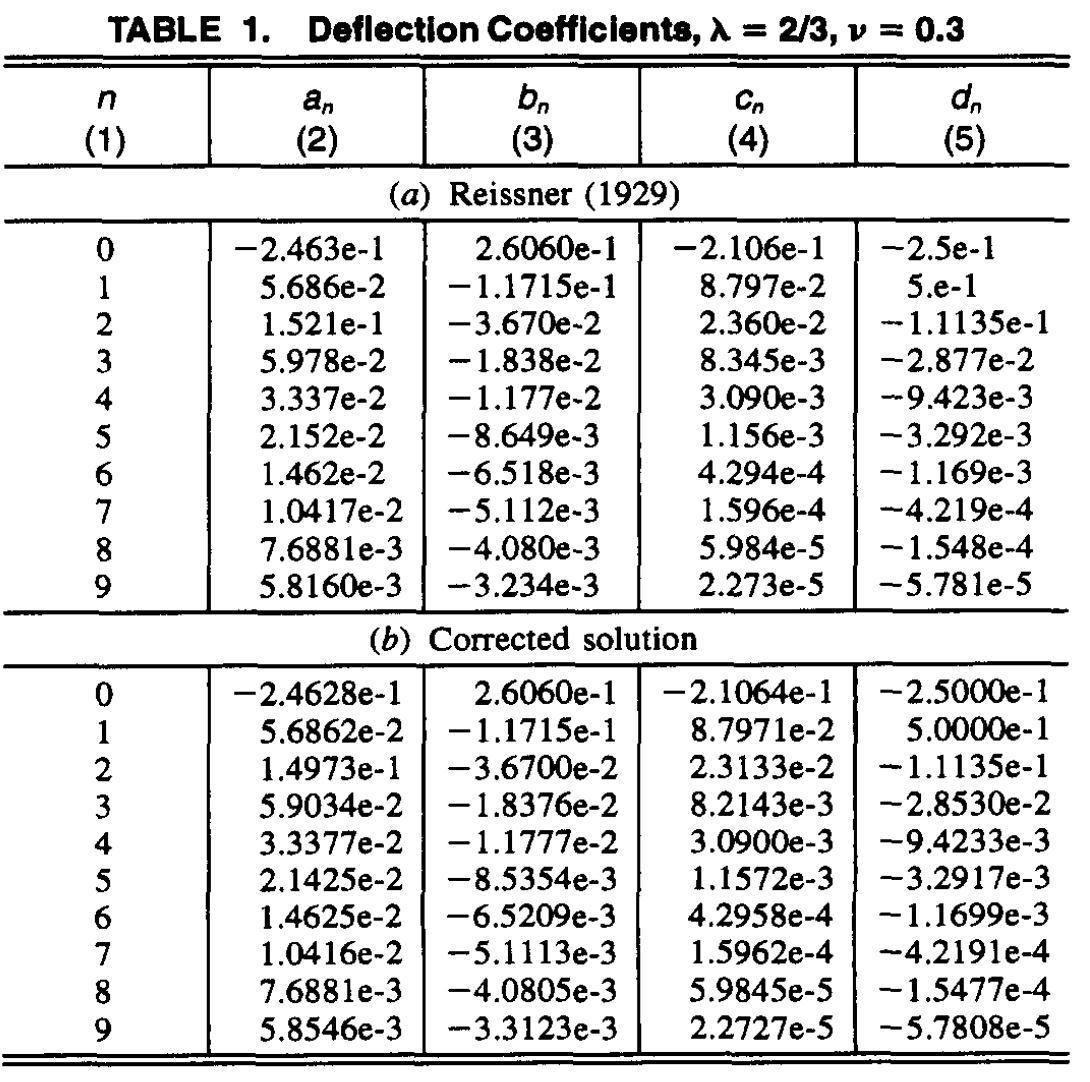

Mr_nondim'

ans =   -4.4222e+00
  -1.4283e+00
  -2.3439e-02
   4.5735e-02
   8.4898e-03
  -7.6379e-05
  -2.9049e-04
  -4.4280e-05
   3.6329e-06


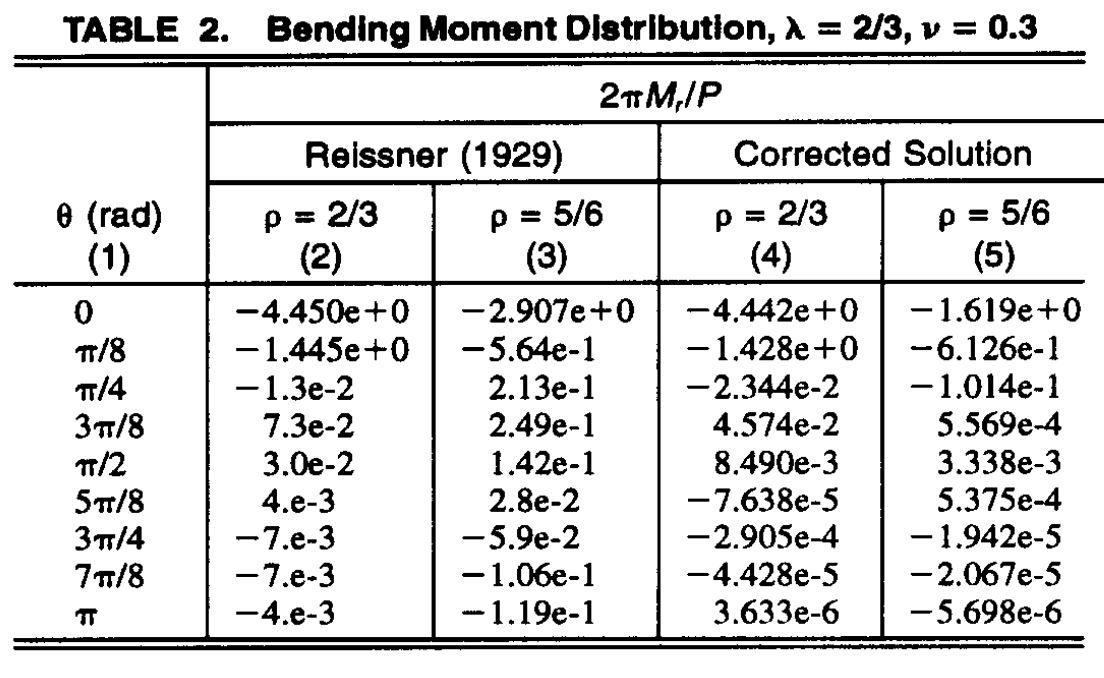

sigma_nondim = 3/pi * abs(Mr_nondim(1))

sigma_nondim =    4.2229e+00


format default

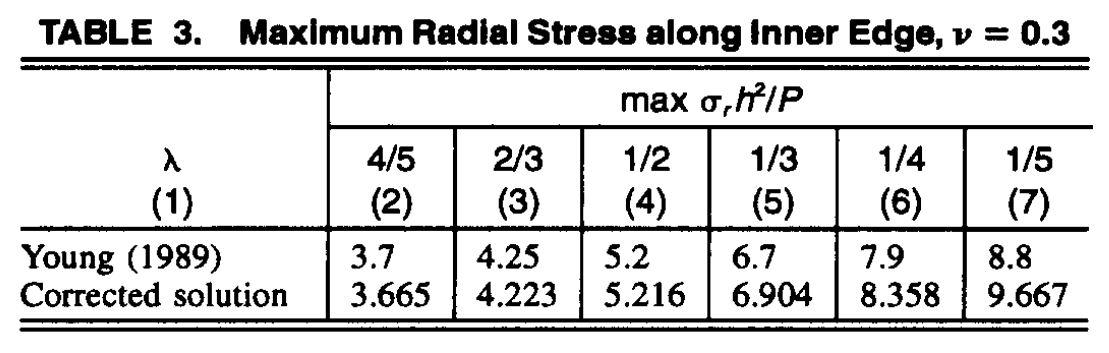

## Plot deflection and bending moment for RM3 geometry, just point loads

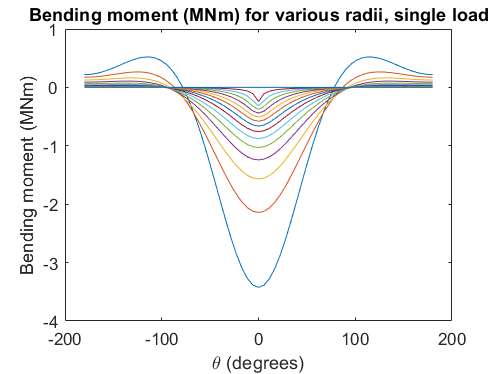

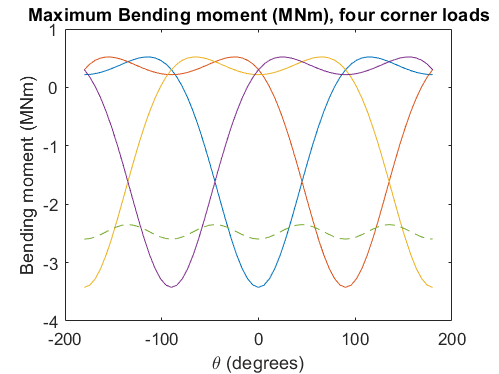

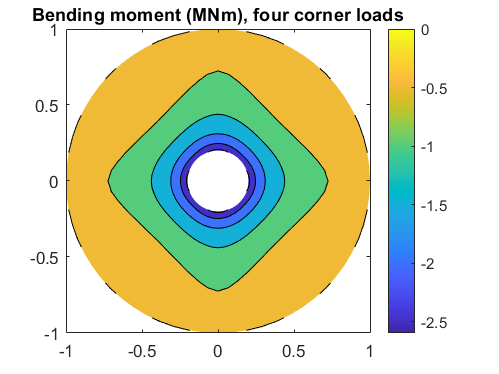

theta = 0:pi/32:pi;
b = 3; % inner radius
a = 15; % outer radius
h = 0.0254; % thickness
F_heave = 8.5e6; % force distributed on bottom
P = F_heave/4; % force per support
E = 210e9;
sigma_y = 248e6;

D = E * h^3 / (12*(1-nu^2));
lam = b/a;
rho = linspace(lam,1,15);

[w_nondim,Mr_nondim] = calc_plate(lam,nu,theta,rho,N);

Mr_dim = Mr_nondim * P/(2*pi);
sigma_dim = Mr_nondim * 3/pi * P/h^2;
FOS = sigma_y ./ sigma_dim;
FOS(abs(FOS)>3) = sign(FOS(abs(FOS)>3)) * 3;
w_dim = w_nondim * P*a^2/(2*pi*D);

w_normalized = w_nondim / max(abs(w_nondim),[],'all');
Mr_normalized = Mr_nondim / max(abs(Mr_nondim),[],'all');

idx_max = 1; % max bending moment occurs at inner edge
%make_four_loads_plot(theta,rho,Mr_normalized,idx_max,'Normalized bending moment (-)')
make_four_loads_plot(theta,rho,Mr_dim/1e6,idx_max,'Bending moment (MNm)',false)

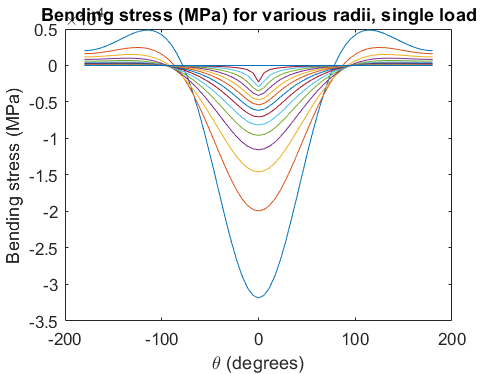

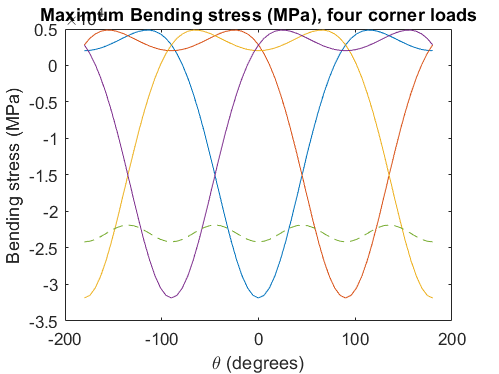

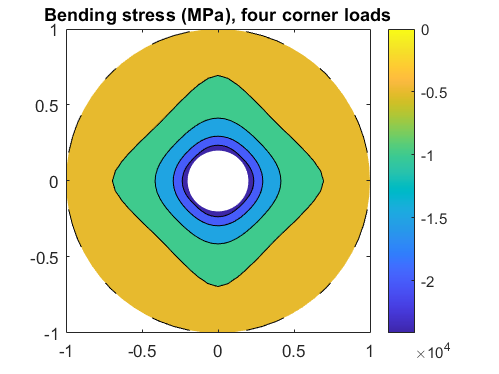

make_four_loads_plot(theta,rho,sigma_dim/1e6,idx_max,'Bending stress (MPa)',false)

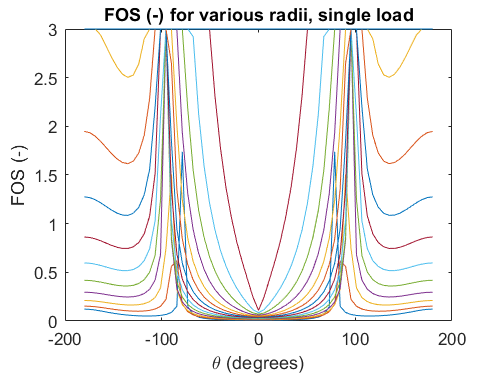

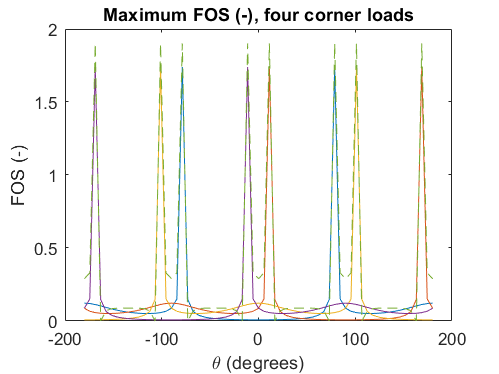

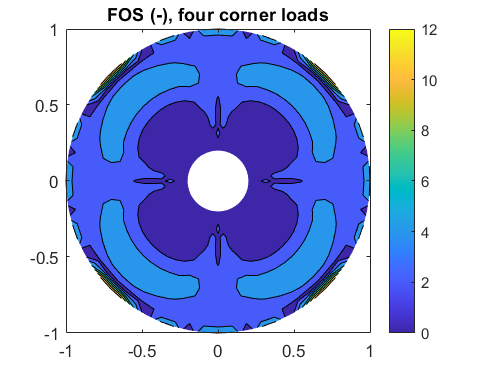

make_four_loads_plot(theta,rho,FOS,idx_max,'FOS (-)',true)

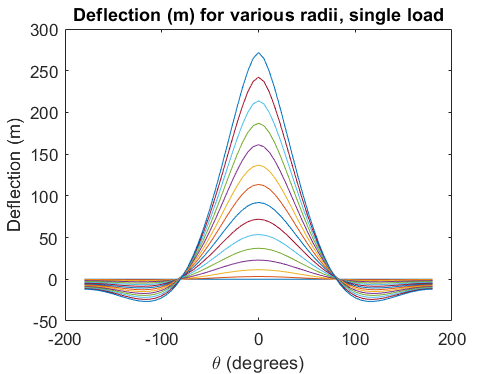

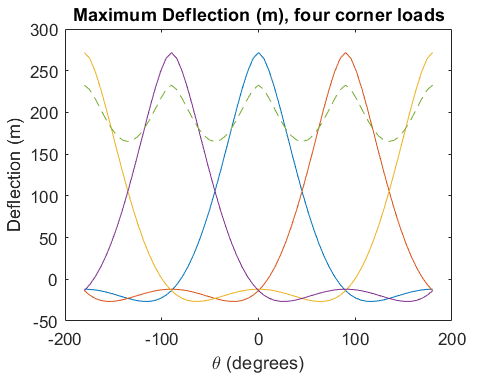

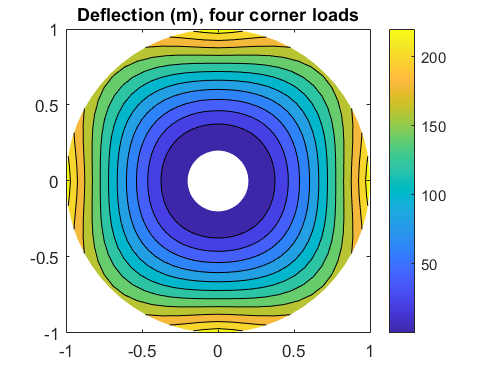


idx_max = length(rho); % max deflection occurs at outer edge
%make_four_loads_plot(theta,rho,w_normalized,idx_max,'Normalized deflection (-)')
make_four_loads_plot(theta,rho,w_dim,idx_max,'Deflection (m)',false)

## Superpose distributed loading

[w_nondim,Mr_nondim] = calc_plate_superposed(a,b,F_heave,nu,theta,rho,N)

w_nondim =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0119    0.0118    0.0114    0.0107    0.0098    0.0088    0.0076    0.0063    0.0050    0.0037    0.0025    0.0014    0.0003   -0.0006   -0.0014   -0.0021   -0.0026   -0.0030   -0.0033   -0.0035   -0.0036   -0.0037   -0.0036   -0.0036   -0.0034   -0.0033   -0.0032   -0.0030   -0.0029   -0.0028   -0.0027   -0.0027   -0.0027
    0.0414    0.0409    0.0395    0.0372    0.0342    0.0306    0.0265    0.0222    0.0178    0.0134    0.0092    0.0052    0.0016   -0.0015   -0.0043   -0.0066   -0.0085   -0.0100   -0.0111   -0.0118   -0.0122   -0.0124   -0.0123   -0.0121   -0.0118   -0.0114   -0.0110   -0.0106   -0.0102   -0.0099   -0.0097   -0.0095   -0.0

Mr_nondim =   -11.3499  -11.2402  -10.9170  -10.3980   -9.7102   -8.8880   -7.9698   -6.9950   -6.0016   -5.0238   -4.0908   -3.2258   -2.4460   -1.7626   -1.1817   -0.7045   -0.3283   -0.0473    0.1465    0.2630    0.3129    0.3077    0.2586    0.1769    0.0733   -0.0425   -0.1615   -0.2758   -0.3787   -0.4645   -0.5290   -0.5689   -0.5824
   -7.1719   -7.1122   -6.9360   -6.6522   -6.2746   -5.8205   -5.3094   -4.7616   -4.1968   -3.6330   -3.0861   -2.5692   -2.0925   -1.6635   -1.2867   -0.9644   -0.6966   -0.4815   -0.3160   -0.1958   -0.1156   -0.0700   -0.0529   -0.0586   -0.0812   -0.1152   -0.1556   -0.1978   -0.2379   -0.2726   -0.2993   -0.3160   -0.3217
   -5.2336   -5.1892   -5.0589   -4.8502   -4.5748   -4.2469   -3.8816   -3.4937   -3.0972   -2.7040   -2.3243   -1.9661   -1.6357   -1.3372   -1.0732   -0.8449   -0.6522   -0.4940   -0.3682   -0.2722   -0.2029   -0.1567   -0.1301   -0.1193   -0.1208   -0.1311   -0.1469   -0.1655   -0.1843   -0.2012   -0.2144   -0.2229   -0.

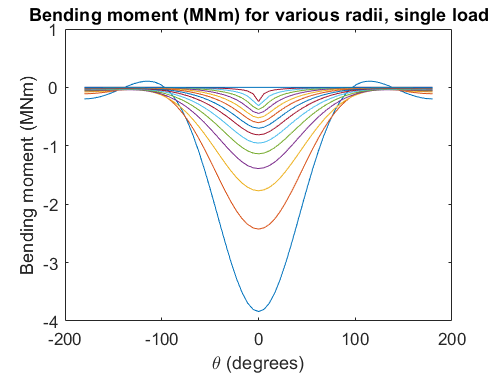

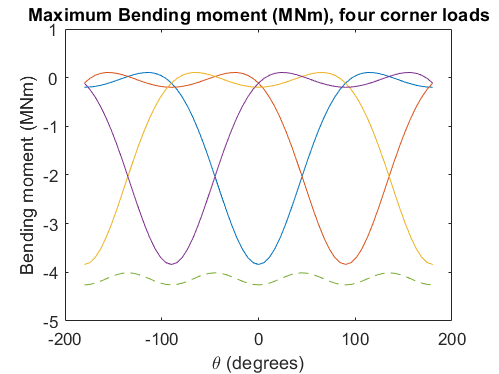

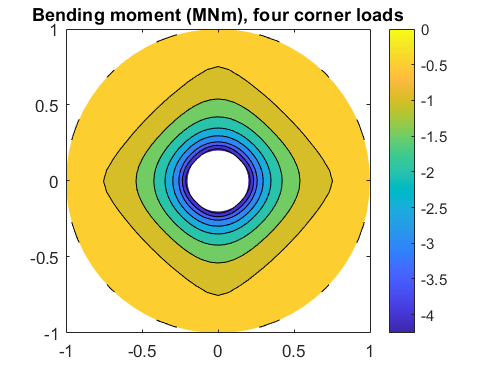

w_dim = w_nondim * P*a^2/(2*pi*D);
Mr_dim = Mr_nondim * P/(2*pi);
sigma_dim = Mr_nondim * 3/pi * P/h^2;

idx_max = 1; % max bending moment occurs at inner edge
make_four_loads_plot(theta,rho,Mr_dim/1e6,idx_max,'Bending moment (MNm)',false)

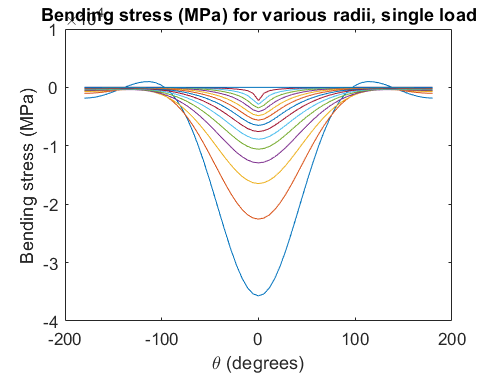

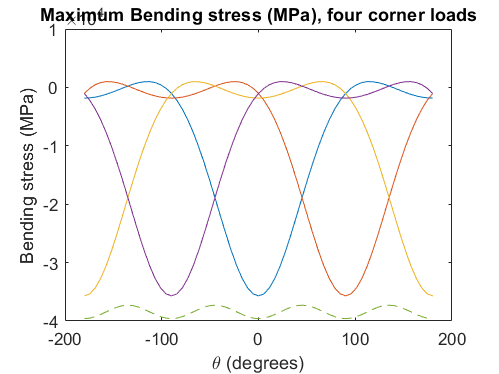

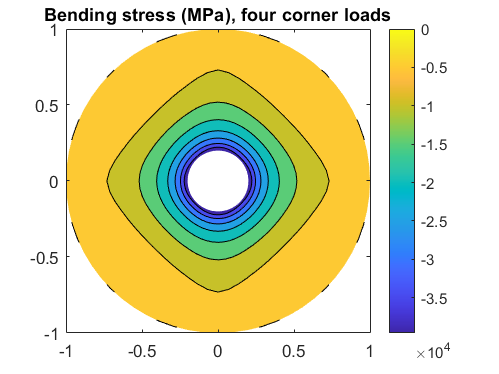

make_four_loads_plot(theta,rho,sigma_dim/1e6,idx_max,'Bending stress (MPa)',false)

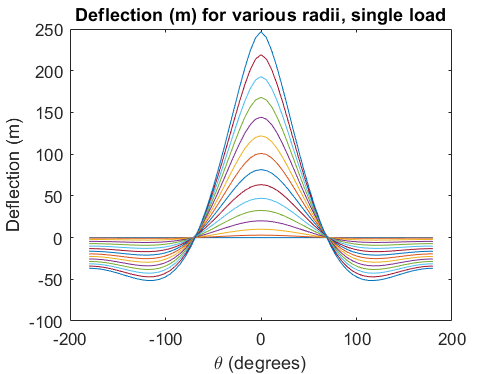

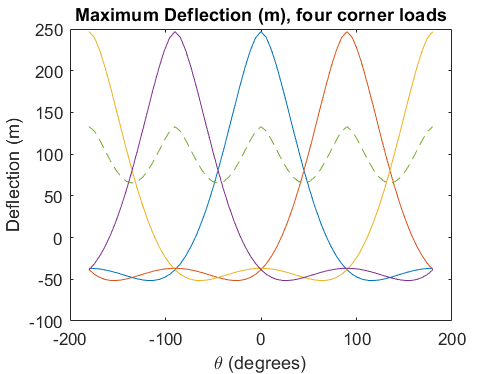

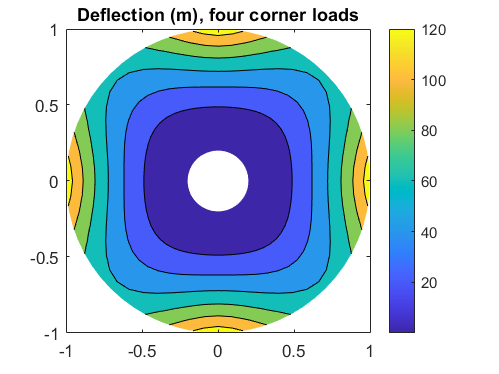

%make_four_loads_plot(theta,rho,FOS,idx_max,'FOS (-)',true)

idx_max = length(rho); % max deflection occurs at outer edge
%make_four_loads_plot(theta,rho,w_normalized,idx_max,'Normalized deflection (-)')
make_four_loads_plot(theta,rho,w_dim,idx_max,'Deflection (m)',false)

## functions

function [theta_shift,x_shift] = shift(theta, x, delta_theta)
% fixme: if I wanted to make a contour plot of deflection or Mr over a
% theta/rho mesh, I need to fix this function to accept matrix inputs for x
    theta_shift = wrapToPi(theta + delta_theta);
    [theta_shift,sort_idx] = sort(theta_shift);
    [theta_shift,unique_idx] = unique(theta_shift);
    sort_idx = sort_idx(unique_idx);
    x_shift = x(:,sort_idx);

    % add start point that equals end point
    if theta_shift(1)+2*pi ~= theta_shift(end)
        theta_shift = [theta_shift(end)-2*pi theta_shift];
        x_shift = [x_shift(:,end) x_shift];
    end
end

function [w_nondim,Mr_nondim] = calc_plate_superposed(a,b,F_heave,nu,theta,rho,N)
    lam = b/a;
    [w_nondim_conc,Mr_nondim_conc] = calc_plate(lam,nu,theta,rho,N);
    [w_nondim_dist,Mr_nondim_dist] = plate_distributed(a,b,F_heave,nu,rho);
    w_nondim = w_nondim_conc   + w_nondim_dist'/4;
    Mr_nondim = Mr_nondim_conc + Mr_nondim_dist'/4;
end

function [w_nondim,Mr_nondim,Mt_nondim] = plate_distributed(a,b,F_heave,nu,rho)
    A = pi*a^2;
    q = F_heave/A;
    P = F_heave/4;
    v = nu;
    r = rho*a;
    r0 = b;

    C2 = 1/4*(1-(b/a)^2*(1+2*log(a/b)));
    C3 = b/4/a*(((b/a)^2+1)*log(a/b)+(b/a)^2-1);
    C8 = 1/2*(1+v+(1-v)*(b/a)^2);
    C9 = b/a*((1+v)/2*log(a/b)+(1-v)/4*(1-(b/a)^2));
    %L3 = r0/4/a*(((r0/a)^2+1)*log(a/r0)+(r0/a)^2-1); % for case 1L
    %L9 = r0/a*((1+v)/2*log(a/r0)+(1-v)/4*(1-(r0/a)^2)); % for case 1L
    L11 = 1/64*(1+4*(r0/a)^2-5*(r0/a)^4-4*(r0/a)^2*(2+(r0/a)^2)*log(a/r0)); % for end deflection only
    L17 = 1/4*(1-(1-v)/4*(1-(r0/a)^4)-(r0/a)^2*(1+(1+v)*log(a/r0)));
    F2 = 1/4 * (1 - (b./r).^2.*(1+2*log(r/b)));
    F3 = b./(4*r) .* ( ( (b./r).^2 + 1 ).*log(r/b) + (b./r).^2 - 1);
    F8 = 1/2 * (1+v+(1-v)*(b./r).^2);
    F9 = b./r .* (1/2*(1+v)*(log(r/b)) + 1/4*(1-v)*(1-(b./r).^2));

    bracket = zeros(size(r));
    bracket(r > r0) = 1;

    ratio = r0./r;
    G11 = 1/64 * (1 + 4*ratio.^2 - 5*ratio.^4 - 4*ratio.^2.*(2+ratio.^2).*log(1./ratio) ) .* bracket;
    G17 = 1/4 * (1 - ((1-v)/4)*(1-ratio.^4) - (ratio).^2.*(1+(1+v)*log(1./ratio))) .* bracket;

    Mrb = -q*a^2/C8 * (C9*(a^2-r0^2)/(2*a*b) - L17);
    Qb = q/2/b * (a^2 - r0^2);
    E = 0;% fixme 
    D = 0; % fixme E*h^3/12/(1-v^2);

    y_over_D = Mrb * r.^2 .* F2 ...
              + Qb * r.^3 .* F3 ...
              - q  * r.^4 .* G11;
    w_nondim = y_over_D * 2*pi/(P*a^2);
    tilt_angle = 0; % fixme use equation for theta on p463

    Mr = Mrb*F8 + Qb*r.*F9 - q*r.^2.*G17;
    Mt = tilt_angle*D*(1-nu^2)./r + nu*Mr;

    Mr_nondim = Mr * 2*pi/P;
    Mt_nondim = Mt * 2*pi/P;
end

function [w_nondim,Mr_nondim,abcd] = calc_plate(lam,nu,theta,rho,N)
    assert(isscalar(lam))
    assert(isscalar(nu))
    assert(isscalar(N))
    % vector inputs only allowed for theta and rho

    [RHO,n] = meshgrid(rho,2:N);
    d0 = -1/4;
    c0_num = (1 + 2*log(lam)) * (1+nu) - (3+nu);
    c0_den = lam^(-1)*(1+nu) + lam*(1-nu);
    c0 = lam/4 * c0_num / c0_den;
    b0 = c0/2 * (1-nu)/(1+nu) + (3+nu)/(8*(1+nu));
    a0 = -lam^2*b0 - c0*log(lam) - d0*lam^2*log(lam);
    
    d1 = 1/2;
    b1 = -1/4 * (1+nu+lam^2*(1-nu)) / (3+nu+lam^4*(1-nu));
    c1 = -b1*(3+nu)/(1-nu) - 1/4 * (1+nu)/(1-nu);
    a1 = -b1*lam^2 - c1*lam^(-2) - d1*log(lam);
    
    A = (3+nu)/(1-nu);
    B = (1-lam^2)^2 * (n.^2-1) + (lam.^(-2*n+2)+A) .* (lam.^(2*n+2)+A);
    
    dn_num = (1-lam^2)*(n-1) + lam.^( 2*n+2) + A;
    bn_num = (1-lam^2)*(n+1) - lam.^(-2*n+2) - A;
    dn_denom = B.*n.*(n-1)*(1-nu);
    bn_denom = B.*n.*(n+1)*(1-nu);
    dn = -dn_num ./ dn_denom;
    bn =  bn_num ./ bn_denom;
    an = -lam^2 * (bn .* (n+1)./n + dn .* lam.^(-2*n)./n);
    cn = -lam^2 * (dn .* (n-1)./n - bn .* lam.^( 2*n)./n);
    
    if length(rho)==1
    abcd  = [a0 b0 c0 d0;
             a1 b1 c1 d1;
             an bn cn dn];
    end
    
    Rho_zero_terms = a0 + b0 * rho.^2 + c0 * log(rho) + d0 * rho.^2 .* log(rho);
    Rho_one_terms = a1*rho + b1 * rho.^3 + c1 * rho.^(-1) + d1 * rho .* log(rho);

    
    Rho_two_to_N_terms = an .* RHO.^n + bn .* RHO.^(n+2) + cn .* RHO.^(-n) + dn .* RHO.^(-n+2);
    
    w_nondim = Rho_zero_terms' + Rho_one_terms' * cos(theta) + Rho_two_to_N_terms' * cos(n(:,1)*theta);
    
    e0_d0_coeff = 3 + nu + 2*(1+nu)*log(rho);
    e0 = 2*b0*(1+nu) - c0*rho.^-2*(1-nu) + d0*(e0_d0_coeff);
    e1 = 2*b1*rho*(3+nu) + 2*c1*rho.^-3*(1-nu) + d1*rho.^-1*(1+nu);
    
    en_a_term = an .* RHO.^(n-2) .* n .* (n-1) * (1 - nu);
    en_b_term = bn .* RHO.^n .* (n+1) .* (n + 2 - nu*(n-2));
    en_c_term = cn .* RHO.^(-n-2) .* n .* (n+1) * (1-nu);
    en_d_term = dn .* RHO.^-n .* (n-1) .* (n-2 - nu*(n+2));
    en = en_a_term + en_b_term + en_c_term + en_d_term;
    Mr_nondim = -1 * (e0' + e1'*cos(theta) + en'*cos(n(:,1)*theta));
end

function [] = make_four_loads_plot(theta,rho,result,idx_max,title_string, take_abs)
    theta_full = [fliplr(-theta) theta];
    result_full = [fliplr(result) result];

    if take_abs
        result_full_plot = abs(result_full);
    else
        result_full_plot = result_full;
    end

    figure
    plot(180/pi*theta_full, result_full_plot)
    xlabel('\theta (degrees)')
    ylabel(title_string)
    title([title_string ' for various radii, single load'])
    
    [theta_0,result_0] = shift(theta_full,result_full,0);
    [theta_90,result_90] = shift(theta_full,result_full,pi/2);
    [theta_180,result_180] = shift(theta_full,result_full,pi);
    [theta_270,result_270] = shift(theta_full,result_full,3*pi/2);
    
   
    result_0_max   = result_0(idx_max,:); 
    result_90_max  = result_90(idx_max,:); 
    result_180_max = result_180(idx_max,:); 
    result_270_max = result_270(idx_max,:); 
    
    result_max_total = result_0_max + result_90_max + result_180_max + result_270_max;

    if take_abs % abs each one AFTER taking the sum, to allow positives and negatives to cancel in sum
        result_0_max = abs(result_0_max);
        result_90_max = abs(result_90_max);
        result_180_max = abs(result_180_max);
        result_270_max = abs(result_270_max);
        result_max_total = abs(result_max_total);
    end

    figure
    plot(180/pi*theta_0,result_0_max)
    hold on
    plot(180/pi*theta_90,result_90_max)
    plot(180/pi*theta_180,result_180_max)
    plot(180/pi*theta_270,result_270_max)
    plot(180/pi*theta_0, result_max_total,'--')
    xlabel('\theta (degrees)')
    ylabel(title_string)
    title(['Maximum ' title_string ', four corner loads'])
    
    figure
    x = rho'*cos(theta_0);
    y = rho'*sin(theta_0);
    z = result_0 + result_90 + result_180 + result_270;
    if take_abs
        z = abs(z);
    end
    contourf(x,y,z)
    colorbar
    axis equal
    title([title_string ', four corner loads'])
end